# Video Labeling (Annotation)

Please see [this livescript](matlab:open('how_to_use_livescript.mlx')) to run and proceed workshop contents.

Annotate target coordinates (x, y) using video labeler app

## Initialization

clear; close all; clc; rng('default');
show_message("annotateVideo",1);

What is initialization?
Actually, these three commands have the following meanings. 
* <a href="https://jp.mathworks.com/help/matlab/ref/clear.html">clear</a>    : Initilize workspace 
* <a href="https://jp.mathworks.com/help/matlab/ref/close.html?s_tid=doc_ta">close all</a>: Close all figures 
* <a href="https://jp.mathworks.com/help/matlab/ref/clc.html?s_tid=doc_ta">clc</a>      : Initilize command window
These are the common commands in MATLAB!

## Generate a video for labeling

% Get video list
videoDS = fileDatastore('.','FileExtensions','.avi','ReadFcn',@(file)vision.VideoFileReader(file));

% Processed per video file
for k = 1:numel(videoDS.Files)
    [dirname,filename,ext] = fileparts(videoDS.Files{k});

    writeFilename = fullfile(dirname,[filename,'_for_labeler.mp4']);
    if ~exist(writeFilename,'file')
        % Set the object for writing video data
        videoWriter = vision.VideoFileWriter(writeFilename,...
            'FileFormat','MPEG4','Quality',90);

        % Set the object for reading video data
        videoReader = vision.VideoFileReader(videoDS.Files{k});
        videoReader.VideoOutputDataType = 'uint8';

        % Read the video sequentially and draw the first labeling point
        while ~videoReader.isDone
            I = videoReader();
            % Draw a mrker circle
            I = insertShape(I,"FilledCircle",[size(I,2)/2, size(I,1)-10,5],"Color","red");
            % Draw comment
            I = insertText(I,[size(I,2)/2+5, size(I,1)-10],"←Click here first",...
                "AnchorPoint","leftCenter","Font","MS PGothic","TextColor","red");
            % Write a video
            videoWriter(I);
        end

        % Finalize the video
        release(videoWriter);
    end
end
show_message("annotateVideo",2);

Now, let's create the training data.

## Launch video labeler

videoLabeler

You can also open "Video Labler" by clicking on that from the "Apps" tab in MATLAB

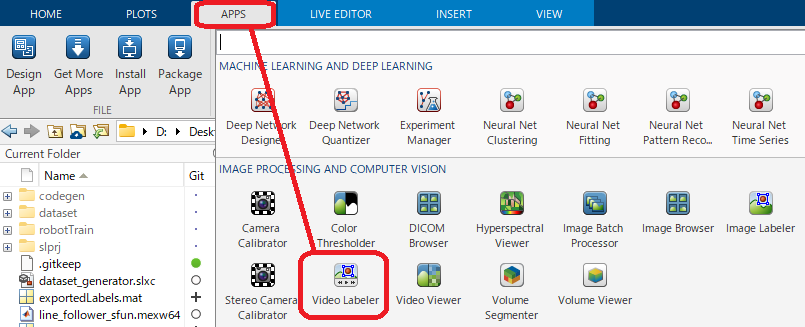

## Import video

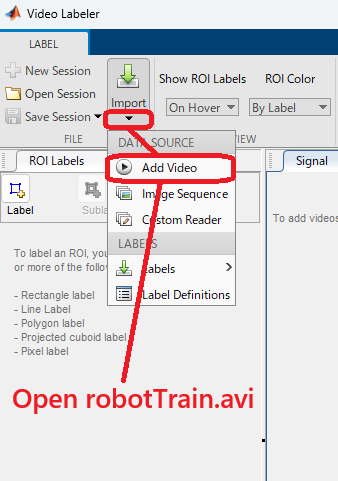

## Define a label

Add label and set label name and type to "WhiteLine" and "Line" respectively.

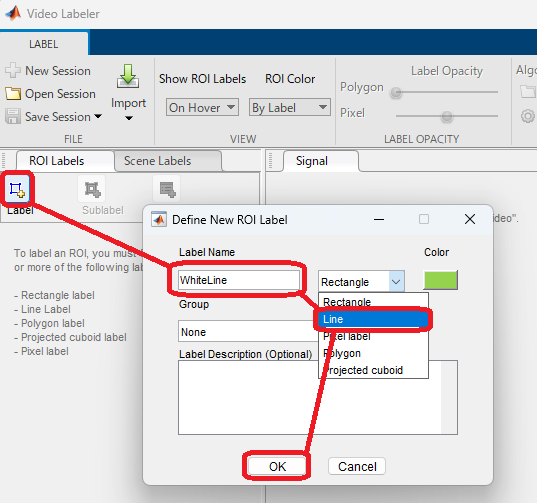

## Labeling target coordinates from bottom to top of image

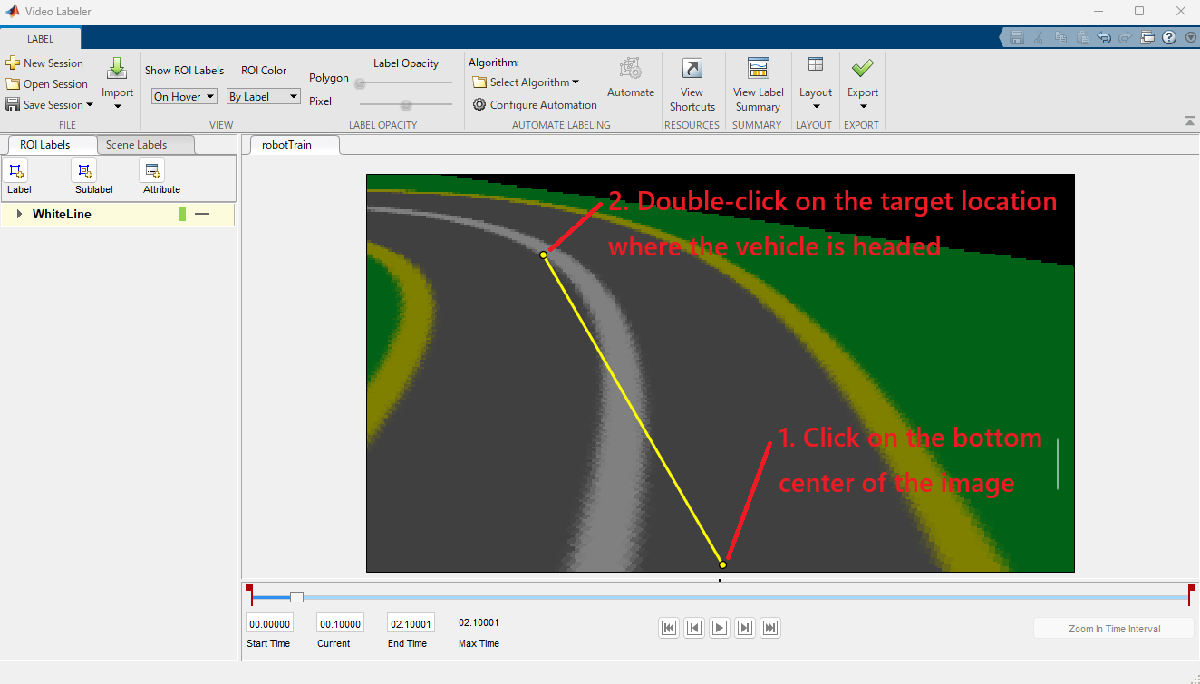

If you end up with a broken line with more than 3 points, right-click to delete and recreate it.

## Save the labeling results as a session

　(You can use default file name)

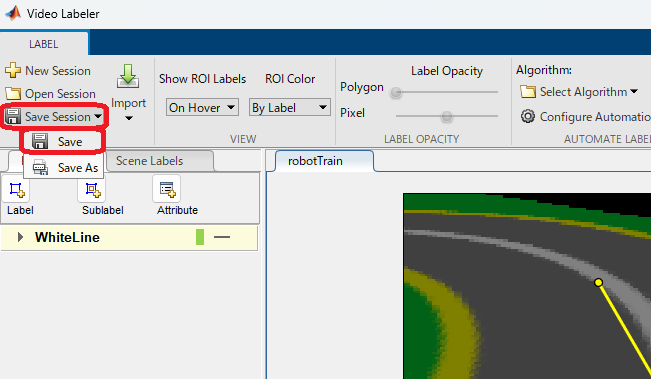

## Save labels

Save as "`exportedLabels.mat"`

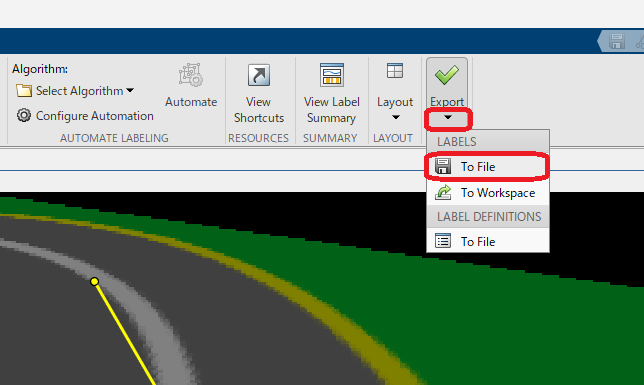

## Next step

Run training of a regression network in [trainWhiteLine.mlx](matlab:open('trainWhiteLine.mlx')) 

## [Return to menu](matlab:open('workshopMenu.mlx'))

*Copyright 2021 The MathWorks, Inc.*